# **2-DOF Robot Arm Simulator**

## **2-DOF Robot Arm**

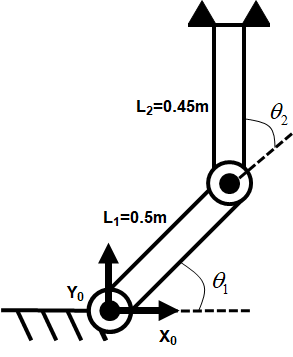

## Need to Know

Rotation Matrix

Transformation Matrix

DH Parameter

Forward & Inverse Kinematics

clc; clear;

## Robot Parameter

   L1 = 0.5;
   L2 = 0.45;
alpha = [0 0 0];
    a = [0 L1 L2];
    d = [0 0 0];
syms dX dY
syms theta1 theta2

## Transformation matrix

T01 = [cos(theta1) -sin(theta1) 0 0
       sin(theta1) cos(theta1)  0 0
       0           0            1 0
       0           0            0 1]

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T12 = [cos(theta2) -sin(theta2) 0 0
       sin(theta2) cos(theta2)  0 0
       0           0            1 0
       0           0            0 1]

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 0\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T23 = [1 0 0 L2
       0 1 0 0
       0 0 1 0
       0 0 0 1]

T23 =     1.0000         0         0    0.4500
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


   
T03 = T01*T12*T23

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & \frac{9\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{20}-\frac{9\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & \frac{9\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}+\frac{9\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{20}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

## Forward Kinematics(End Effector Position)

x = (9*cos(theta1)*cos(theta2))/20 - (9*sin(theta1)*sin(theta2))/20

y = (9*cos(theta1)*sin(theta2))/20 + (9*cos(theta2)*sin(theta1))/20

z = 0

x = T03(1,4)

$$x = \frac{9\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{20}-\frac{9\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}$$

y = T03(2,4)

$$y = \frac{9\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}+\frac{9\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{20}$$

z = T03(3,4)

$$z = 0$$

## Inverse Kinematics

### *q2*

 

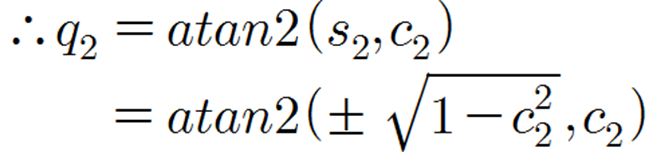

### *q1*

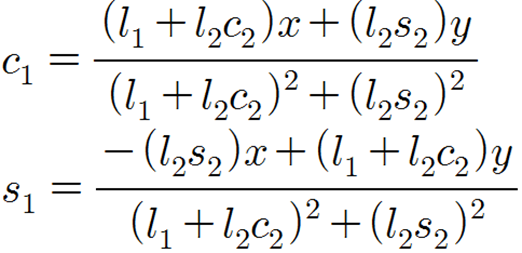

### Result

q2 = atan2((1 - ((9*dX^2)/80 + (9*dY^2)/80 - 1629/32000)^2)^(1/2), (20*dX^2)/9 + (20*dY^2)/9 - 181/180)

q1 = - angle((9*((20*real(dX^2))/9 + (20*real(dY^2))/9 - imag((1 - ((9*dX^2)/80 + (9*dY^2)/80 - 1629/32000)^2)^(1/2)) - 181/180))/(20*abs((1 - ((9*dX^2)/80 + (9*dY^2)/80 - 1629/32000)^2)^(1/2)*1i + (20*dX^2)/9 + (20*dY^2)/9 - 181/180)) + (((20*imag(dX^2))/9 + (20*imag(dY^2))/9 + real((1 - ((9*dX^2)/80 + (9*dY^2)/80 - 1629/32000)^2)^(1/2)))*9i)/(20*abs((1 - ((9*dX^2)/80 + (9*dY^2)/80 - 1629/32000)^2)^(1/2)*1i + (20*dX^2)/9 + (20*dY^2)/9 - 181/180)) + 1/2) + atan2(dX, dY)

q2 = atan2(sqrt( 1 - ( ( dX*dX + dY*dY - 0.45^2 - 0.5^2) / 2*0.45*0.5 )^2), ( (dX*dX + dY*dY - 0.45^2 - 0.5^2) / (2*0.45*0.5) ) )

$$q2 = \text{atan2}\left(\sqrt{1-{\left(\frac{9\,{\mathrm{dX}}^{2}}{80}+\frac{9\,{\mathrm{dY}}^{2}}{80}-\frac{1629}{32000}\right)}^{2}},\frac{20\,{\mathrm{dX}}^{2}}{9}+\frac{20\,{\mathrm{dY}}^{2}}{9}-\frac{181}{180}\right)$$

q1 = atan2(dX, dY) - atan2(0.45 * sin(q2), 0.5 + 0.45 * cos(q2))

$$q1 = \begin{array}{l} -\text{angle}\left(\frac{9\,\left(\frac{20\,\mathrm{real}\left({\mathrm{dX}}^{2}\right)}{9}+\frac{20\,\mathrm{real}\left({\mathrm{dY}}^{2}\right)}{9}-\mathrm{imag}\left(\sigma_{2}\right)-\frac{181}{180}\right)}{\sigma_{1}}+\frac{1}{2}+\frac{9\,\left(\frac{20\,\mathrm{imag}\left({\mathrm{dX}}^{2}\right)}{9}+\frac{20\,\mathrm{imag}\left({\mathrm{dY}}^{2}\right)}{9}+\mathrm{real}\left(\sigma_{2}\right)\right)\,\mathrm{i}}{\sigma_{1}}\right)+\text{atan2}\left(\mathrm{dX},\mathrm{dY}\right)\\ \mathrm{where}\\ \sigma_{1}=20\,\left|\frac{20\,{\mathrm{dX}}^{2}}{9}+\frac{20\,{\mathrm{dY}}^{2}}{9}-\frac{181}{180}+\sigma_{2}\,\mathrm{i}\right|\\ \sigma_{2}=\sqrt{1-{\left(\frac{9\,{\mathrm{dX}}^{2}}{80}+\frac{9\,{\mathrm{dY}}^{2}}{80}-\frac{1629}{32000}\right)}^{2}} \end{array}$$